clear all
close all
clc


## Loading all the data

Specify the date and the type of the sample

date='230606'

date = '230606'

sample='C2_r3_p012'

sample = 'C2_r3_p012'



for ii=1:20 %based on 20 segments
    vname1=sprintf('top_IR%d',ii);
    for jj=1:9
        
        vname2=sprintf('m%d',jj);
        ii=num2str(ii);
        jj=num2str(jj-1);
    
        data.(vname1).(vname2)=imread(['C:\Users\CopsLAB_Local\Documents\CJ_measurements\' date '_' sample '\top_IR' ii 'a\' jj '.tif']);
    end
    
end

for ii=1:20 %based on 20 segments
    vname1=sprintf('top_LED%d',ii);
    for jj=1:9
        
        vname2=sprintf('m%d',jj);
        ii=num2str(ii);
        jj=num2str(jj-1);
    
        data.(vname1).(vname2)=imread(['C:\Users\CopsLAB_Local\Documents\CJ_measurements\' date '_' sample '\top_LED' ii 'a\' jj '.tif']);
    end
    
end



## Finding the edge

This part of the code finds the edge of the samples.


for jj=1:20
    vname1=sprintf('top_LED%d',jj);
    BW=edge(data.(vname1).m1,'Sobel',0.02,'vertical');
    %imshowpair(BW,data.top_LED9.m1,'montage');
    threshold=100;
    ii=6;
    while sum(sum(BW(:,ii-3:ii+3)))<threshold
        ii=ii+1;
        vedge.(vname1)=ii;
    end
end



## Data analysis

figure('Name','yslice')
hold on
c=parula(7)

c =     0.2422    0.1504    0.6603
    0.2780    0.3556    0.9777
    0.1540    0.5902    0.9218
    0.0704    0.7457    0.7258
    0.5044    0.7993    0.3480
    0.9871    0.7348    0.2438
    0.9769    0.9839    0.0805


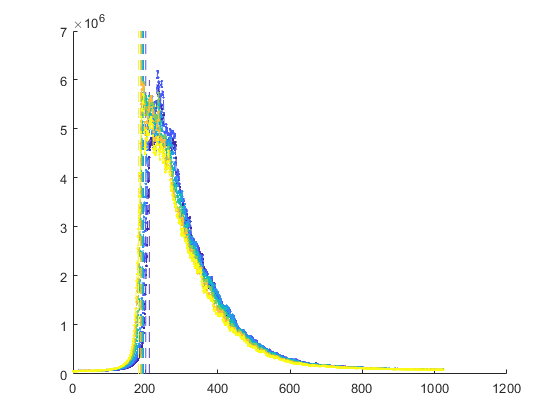

for ii=7:13
   vname1=sprintf('top_IR%d',ii);
   vname2=sprintf('top_LED%d',ii);
   plot(sum(data.(vname1).m1),'--.','color',c(ii-6,:))
   y=ylim; %before 2018
   plot([vedge.(vname2) vedge.(vname2)],[y(1) y(2)],'--','color',c(ii-6,:)) %before 2018
   %plot([vedge.(vname2) vedge.(vname2)],[y(1) y(2)],'k--')%'color',c(ii,:))
   %xline(vedge.(vname2),'color',c(ii,:)) after 2018
end